# Stock Data - Modeling the Markets I

## 1.

Load data from `stockData_withReturns.mat`. This file contains daily prices and returns in `stockPrices`and `rets`respectively, information about these stocks in `stockInfo`, and market index prices in the table `benchmark`.

load stockData_withReturns.mat

## 2.

Extract the prices for all of the market indices found in `benchmark`and convert into returns using:

`benchRets``= diff(log(``benchPrices``))`

benchPrices = benchmark{:, 2:end}

benchPrices = 	1.0e+04 *

    0.1309    0.2361    1.1217    0.0766    0.0059    0.0050    0.0014    0.0005    0.0003    0.1099    0.1112    0.0097    0.0201    0.0005    0.0005
    0.1295    0.2339    1.1120    0.0756    0.0058    0.0050    0.0014    0.0005    0.0003    0.1088    0.1097    0.0097    0.0201    0.0005    0.0005
    0.1297    0.2333    1.1141    0.0753    0.0059    0.0050    0.0014    0.0005    0.0003    0.1090    0.1113    0.0097    0.0201    0.0005    0.0005
    0.1287    0.2310    1.1090    0.0742    0.0058    0.0049    0.0014    0.0005    0.0003    0.1085    0.1106    0.0097    0.0201    0.0005    0.0005
    0.1288    0.2315    1.1130    0.0748    0.0058    0.0049    0.0014    0.0005    0.0003    0.1084    0.1107    0.0097    0.0201    0.0005    0.0005
    0.1289    0.2326    1.1138    0.0751    0.0058    0.0049    0.0014    0.0005    0.0003    0.1085    0.1108    0.0097    0.0201    0.0005    0.0005
    0.1285    0.2311    1.1074    0.0749    0.0058    0.0049    0.00

benchRets = diff(log(benchPrices))

benchRets =    -0.0104   -0.0094   -0.0086   -0.0133   -0.0116   -0.0090   -0.0022    0.0142    0.0030   -0.0097   -0.0128   -0.0001    0.0001    0.0006    0.0010
    0.0009   -0.0025    0.0019   -0.0042    0.0019         0   -0.0007         0    0.0030    0.0012    0.0141   -0.0002    0.0003    0.0016    0.0034
   -0.0078   -0.0099   -0.0047   -0.0145   -0.0069   -0.0136   -0.0065   -0.0061    0.0180   -0.0047   -0.0061   -0.0001    0.0001    0.0041    0.0010
    0.0012    0.0019    0.0036    0.0076   -0.0048    0.0020   -0.0007    0.0101   -0.0149   -0.0004    0.0008   -0.0001    0.0001    0.0043    0.0036
    0.0008    0.0049    0.0007    0.0045    0.0026    0.0028   -0.0036    0.0120    0.0120    0.0011    0.0005   -0.0001    0.0001    0.0004    0.0004
   -0.0029   -0.0064   -0.0058   -0.0022    0.0046         0   -0.0044   -0.0060    0.0118   -0.0041    0.0183   -0.0002    0.0004    0.0015    0.0014
    0.0169    0.0193    0.0175    0.0268    0.0202    0.0163    0.0080   -0.0080  

## 3.

Use `grpstats` to find the average daily stock return grouped by `stockInfo.CapSize`. **Hint:** You will need to transpose `rets`.

avRetByCap = grpstats(rets', stockInfo.CapSize, 'mean')';
avSmallCap = avRetByCap(:,1)

avSmallCap =    -0.0069
    0.0074
   -0.0091
   -0.0008
    0.0023
   -0.0001
    0.0054
    0.0113
   -0.0030
    0.0009


avMidCap = avRetByCap(:,2)

avMidCap =    -0.0087
    0.0030
   -0.0152
    0.0063
    0.0093
    0.0063
    0.0199
    0.0139
   -0.0085
    0.0002


avLargeCap = avRetByCap(:,3)

avLargeCap =    -0.0136
    0.0002
   -0.0151
   -0.0000
    0.0043
    0.0040
    0.0233
    0.0094
    0.0000
   -0.0007


## 4.

Perform linear regression on the average small-, mid- and large-cap stock returns separately using all of the benchmark returns as predictor variables. Use a linear model for the stock returns as a function of the benchmark returns.

benchNames = benchmark.Properties.VariableNames(2:end);
smallFit = fitlm(benchRets, avSmallCap, 'linear', 'PredictorVars', benchNames,...
    'ResponseVar', 'smallCap')

smallFit = Linear regression model:
    smallCap ~ [Linear formula with 16 terms in 15 predictors]

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________
    (Intercept)    -0.00065449    0.00025273     -2.5897      0.009716
    SP500              0.26036       0.13472      1.9326       0.05351
    NASDAQ            0.022365      0.062864     0.35576       0.72208
    DJI               -0.32064       0.14395     -2.2275      0.026088
    Russel2000         0.56811      0.042114       13.49    7.7483e-39
    MSCI              0.048053      0.035211      1.3647       0.17259
    EMM                0.34834      0.031946      10.

midFit = fitlm(benchRets, avMidCap, 'linear', 'PredictorVars', benchNames,...
    'ResponseVar', 'midCap')

midFit = Linear regression model:
    midCap ~ [Linear formula with 16 terms in 15 predictors]

Estimated Coefficients:
                    Estimate         SE          tStat        pValue  
                   __________    __________    _________    __________
    (Intercept)    0.00010243    0.00022284      0.45965       0.64584
    SP500             0.10352       0.11879      0.87152       0.38364
    NASDAQ            0.23226      0.055429       4.1902    2.9817e-05
    DJI               -0.6675       0.12692      -5.2591    1.6991e-07
    Russel2000        0.41685      0.037133       11.226    6.1426e-28
    MSCI             0.069859      0.031047       2.2501      0.024612
    EMM               0.25801      0.028168       9.1597 

largeFit = fitlm(benchRets, avLargeCap, 'linear', 'PredictorVars', benchNames,...
    'ResponseVar', 'largeCap')

largeFit = Linear regression model:
    largeCap ~ [Linear formula with 16 terms in 15 predictors]

Estimated Coefficients:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________
    (Intercept)    0.00014456    0.00017254     0.83783       0.40228
    SP500              1.7225      0.091976      18.728    3.0752e-69
    NASDAQ           -0.22315      0.042919     -5.1993    2.3326e-07
    DJI              -0.36367      0.098275     -3.7005    0.00022441
    Russel2000       0.082216      0.028752      2.8594     0.0043138
    MSCI              0.22936       0.02404       9.541    7.0306e-21
    EMM               0.17077      0.021811      7.8295    1.

## 5.

The coefficients of the linear terms in the resultant models are known as *beta* values. Extract these coefficients from the three linear models created in step 4 (you do not need to include the intercept estimate). Concatenate the estimates from all three models into a matrix and create a bar chart of the beta value for each predictor variable.

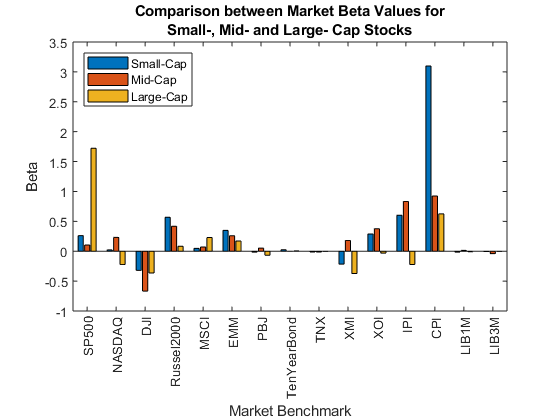

allCoeffs = [smallFit.Coefficients.Estimate, midFit.Coefficients.Estimate,...
    largeFit.Coefficients.Estimate];
% Get rid of intercept term:
allBetas = allCoeffs(2:end,:);

% Create bar chart and change x-tick labels
bar(allBetas)
xticks(1:size(allBetas,1))
xticklabels(benchNames)
xtickangle(90)
title({'Comparison between Market Beta Values for', 'Small-, Mid- and Large- Cap Stocks'})
xlabel('Market Benchmark')
ylabel('Beta')
legend('Small-Cap', 'Mid-Cap', 'Large-Cap', 'Location', 'northwest')